# Homework # 9. 

# Due;Tuesday, May 4 @ 11:59pm

# Solutions

## Problem 1 (10 points)

Consider the pdf of random variable $X$

$p_X(x)=c(a^2-x^2)$, $-a\leq x \leq a$

where $c$ and $a$ are constants. Write an anonymous function `P_de` that takes $a$ as well as two variables $d$ and $e$ as input, and returns Prob $\left( d\leq X \leq e \right)$ as output. You may assume that only inputs that satisfy $d<e$, $-a\leq d < a$ and $-a< e \leq a$ will be given. Make sure to test your function using inputs which lead to known solutions. Hint: the constant *c* should not appear in your solution.

If you prefer to write a function at the bottom of the script, make sure you indicate that in the workspace immediately below.

clear; close All; clc;
% Put your work below
% function at bottom of script; P_de(a,d,e)
P_de(3,1,2)

ans = 0.1852

## Problem 2 (30 points)

We would like to generate random deviates from the distribution $p(x)=4\pi^{-1/2} x^2\exp(-x^2)$, for $0 \leq x<\infty$. When deviates from a desired distribution are not readily available (e.g. via built-in functions), one may use a convenient and general, if inefficient, method to generate them, known as acceptance-rejection. In this method, deviates are generated from a known distribution and accepted based on the ratio of the desired probability to the probability from which the deviate was  generated. 

Here we will implement the simplest case: we will use uniformly distributed random variates (from the `rand` routine). We will also truncate the interval to $0\leq x \leq 5$, since $p(x>5)$ is very small and as you will see below, trying to generate deviates where $p(x)$ is very small is very inefficient. The algorithm proceeds as follows: find an upper bound to $p(x)$, which we will denote as $U$. To generate a variate, generate a candidate uniformly distributed variate, $x_c$ in $0\leq x\leq 5$. Accept this variate with probability $p(x_c)/U$. Proceed to the next candidate until the desired number of variates is generated (accepted).

a) (10 points) Below write some code that will generate N=10,000 variates from $p(x)$. You will test your code in part (b) below. Return your deviates in the vector `deviates`.

clear; close All; clc;

N=10000;
P_desired=@(x) 4/sqrt(pi)*x.^2.*exp(-x.^2);
U = 1;
% Put your work below
deviates = [];
N_cand = 0;
while length(deviates)<N
    x_c = rand([1,1])*5;
    N_cand = N_cand + 1;
    if (P_desired(x_c)/U)>rand([1,1])
        deviates(end+1) = x_c;
    end
end

b) (5 points) Test your code by plotting a histogram of the distribution you created and also by checking the mean and variance of the distribution sample you created with the theoretical values. 

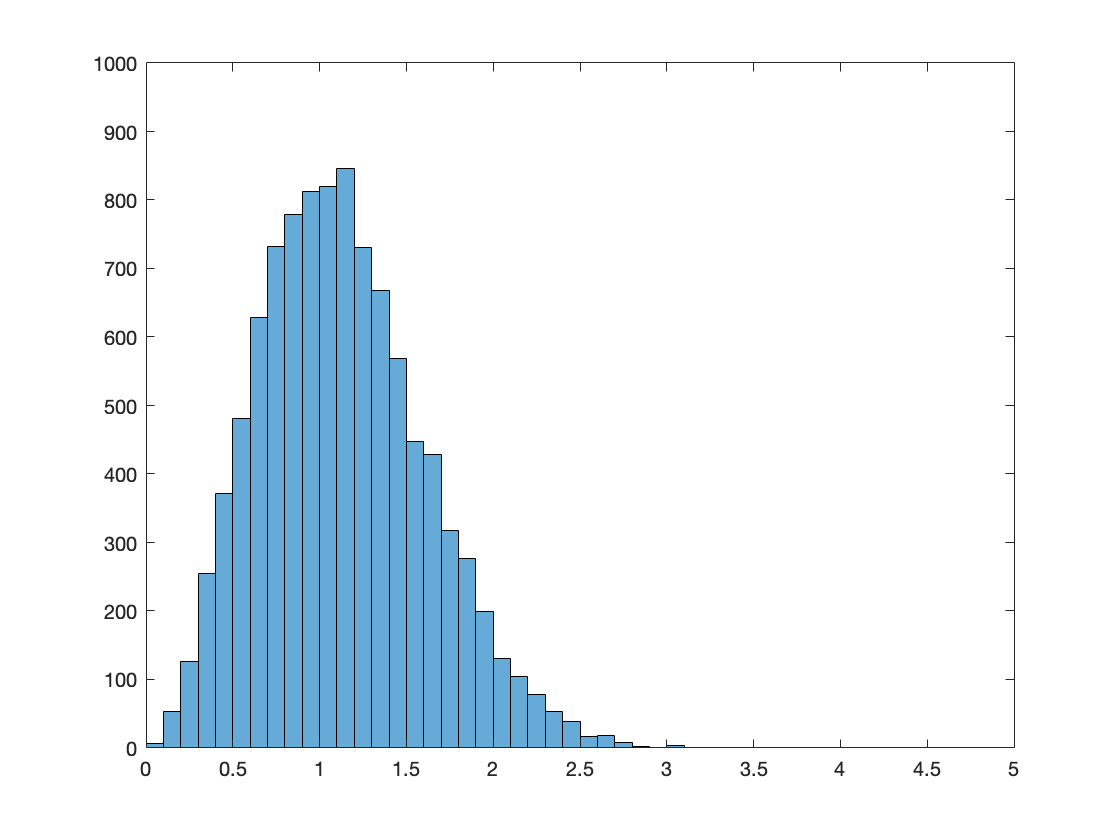

% Put your work below
histogram(deviates)
xlim([0 5])
ylim([0 1000])

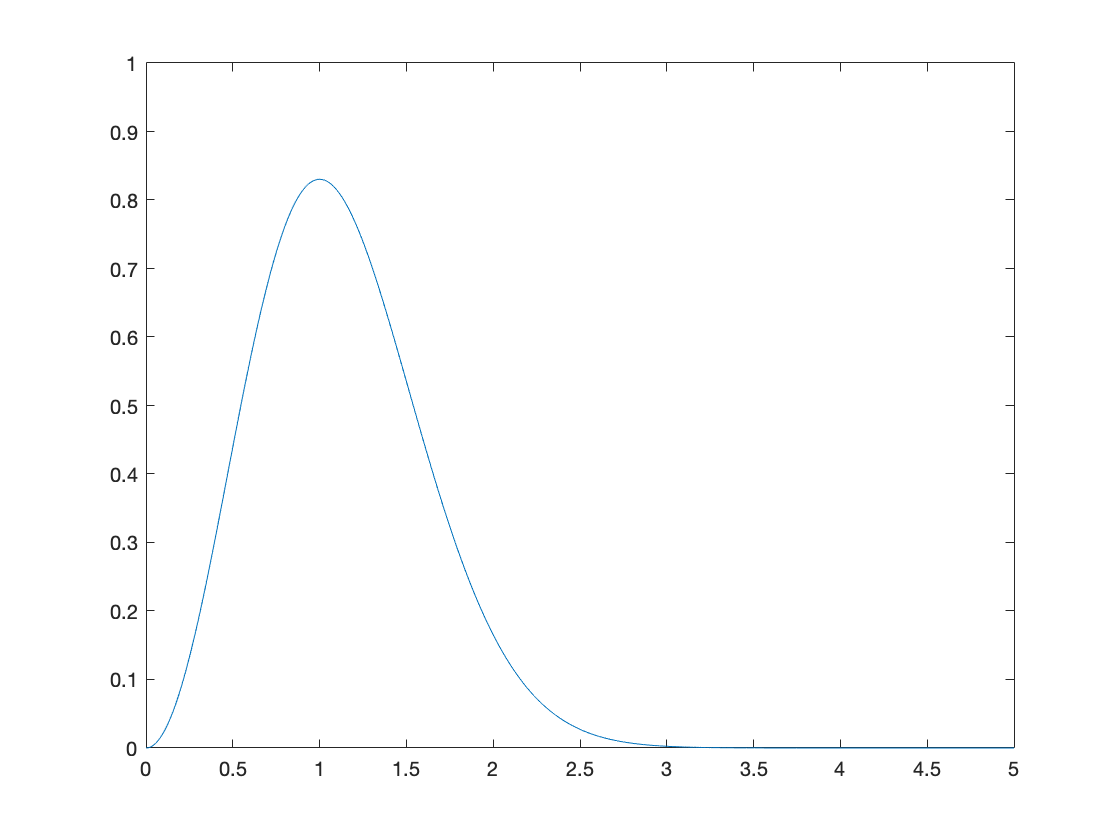

xvals = linspace(0,5,N);
pvals = P_desired(xvals);
plot(xvals,pvals)
xlim([0 5])
ylim([0 1])

deviates_mu = mean(deviates)

deviates_mu = 1.1303

deviates_sig2 = var(deviates)

deviates_sig2 = 0.2257

P_desired_x = @(x) P_desired(x).*x;
theoretical_mu = integral(P_desired_x,0,5)

theoretical_mu = 1.1284

sig2_func = @(x) ((x-theoretical_mu).^2).*P_desired(x);
theoretical_sig2 = integral(sig2_func,0,5)

theoretical_sig2 = 0.2268

c) (5 points) Modify your code above to output the number of candidate variates needed to generate 10,000 variates from $p(x)$. Save this output below in the variable `N_cand`. Calculate the  expected number of candidate variates and save it in the variable `N_cand_th ` (note that $p(x)$ is normalized to 1).

% Put your work below
N_cand

N_cand = 49885

zero_to_five = integral(P_desired,0,5)/5;
N_cand_th = N*(1/zero_to_five)

N_cand_th = 5.0000e+04

d) (5 points) Estimate how many variates would be generated in the range $5 \leq x \leq 10$ had you decided to truncate at $x=10$ and use twice as many candidates (where one would expect half of the candidates to fall in the range $0\leq x \leq 5$ and create 10000 actual variates and the other half of the candidates to fall in the range $5\leq x\leq 10$). Return your answer in the variable `N_2`.

% Put your work below
% 5<=x<=10
five_to_ten = integral(P_desired,5,10)/5;
N_2 = N*(1/five_to_ten)

N_2 = 6.2585e+14

e) (5 points) How can this inefficiency be improved upon?

% Write your answer below
% make U very small i.e. 10^(-11)

## **Problem 3 (10 points)**

Suppose a barrel contains a red and two green balls. What is the probability of drawing a green ball on the second draw (first draw is not replaced). Return your answer in variable P_G_2

clear; close All; clc;

% Put your work below
% P(RR) = 0
% P(RG) = 1/3
% P(GR) = (2/3)*(1/2) = 1/3
% P(GG) = (2/3)*(1/2) = 1/3
P_G_2 = (1/3)+(1/3)

P_G_2 = 0.6667

## Problem 4 (25 points)

Make sure to read the module 8 reading assignment M8_Random_Variables.mlx section 8.7 before solving this problem.

Suppose that we have one unfair coin with an unknown probability $p$ of  landing heads up. This coin is tossed $n= 100$ times and the number of heads observed is 68, making the observed mean $\bar{x}_n= 0.68$

a) (10 points) Find the confidence interval on the mean, `xbar_n`, with $\gamma= 95$%, using the formulas in section 8.7 of the notes (do not use any built-in functions for the confidence interval). Return your confidence interval in terms of the lower bound `CI_l` and upper bound` CI_u`. Hint: For $\gamma= 95$%, $z_\gamma= 1.96$.

clear; close All; clc;

% Here is some starter code
n=100;
num_heads=68;
xbar_n=num_heads/n

xbar_n = 0.6800

gamma=0.95;
z_g=1.96;
% Put your code below and call the lower bound CI_l and upper bound CI_u
half_width=z_g*sqrt(xbar_n*(1-xbar_n)/n);
CI_l = xbar_n-half_width

CI_l = 0.5886

CI_u = xbar_n+half_width

CI_u = 0.7714

b) (15 points) Using $10^5$ trials, test the performance of the confidence interval computed using the procedure from part (a). In other words, repeat the following process $10^5$ times: 

i) Generate a set of 100 coin flips with a probability $p= 0.68$ of turning up heads.

ii) Calculate the confidence interval based on the "data" from that trial. 

iii) Test whether that confidence interval contains the value $p=0.68$ used to generate the random coin flips. 

From these $10^5$ trials show that the confidence interval contains the value $p=0.68$ with relative frequency close to 0.95 (since $\gamma= 95$%). 

% Put your code below and call the observed relative frequency CI_obs
nt = 10^5;
is_in = zeros(1,nt);
for t=1:nt
    X=rand(1,n)<xbar_n; % Create n Bernoulli random values
    x_hat=mean(X); % Compute the unbiased estimate of the parameter
    half_width=z_g*sqrt(x_hat*(1-x_hat)/n); % Use the formula
    CI=[x_hat-half_width x_hat+half_width];
    is_in(t)=(xbar_n>CI(1))&(xbar_n<CI(2)); % Here we test whether the "true" parameter in inside the CI.
    % You can never really do this test when we deal with data from the real world because we don't know 
    % the true parameter value.  But in a computer simulation, we do know it and so we can assess 
    % our procedure's validity.
end
mean(is_in)

ans = 0.9456

## Problem 5 (25 points)

You are approached by a presidential campaign and are asked to help with their data modeling effort. Their candidate (A), has 230 electoral votes (EVs) "in the bag". Their opponent has 218 EVs "in the bag". The remaining 90 EVs are distributed among 6 states as follows: state 1 has 25 EVs, state 2 has 20 Evs, state 3 has 14 EVs, state 4 has 12 EVs, state 5 has 10 EVs and state 6 has 9 EVs. 270 EVs are needed to win. The campaign has high-quality polling data from states 1-6. According to this data, candidate A is projected to receive 48%, 54%, 51%, 50%, 54% and 47% of the vote, respectively. Candidate B is expected to win the complement of the votes in each state. The 95% confidence interval associated with these polls is $\pm$3% in all states except state 4, where it is $\pm$4% and state 6 where it is $\pm$4.5%. In all states, the candidate who secures 50% plus one vote wins all the EVs of the state.

a) (15 points) Develop a code which simulates 10,000 instances of the election based on this probabilistic model.  You may assume that the outcome of each state 1 through 6 is normally distributed with mean and standard deviation as given by the polling model. The output of your code should be a histogram of the possible outcomes (EVs won by candidate A). Make sure you label the histogram clearly.

clear; close All; clc;

N=10000;
mu=[48 54 51 50 54 47];% polling means in states 1-6 for candidate A
stds=[3 3 3 4 3 4.5]/1.96;% polling stds magnitude in states 1-6
EVs=[25 20 14 12 10 9];% EVs of states 1-6
num_states = length(mu);
probs = 1-normcdf(50,mu,stds) %probability that X>=50

probs =     0.0957    0.9955    0.7432    0.5000    0.9955    0.0957


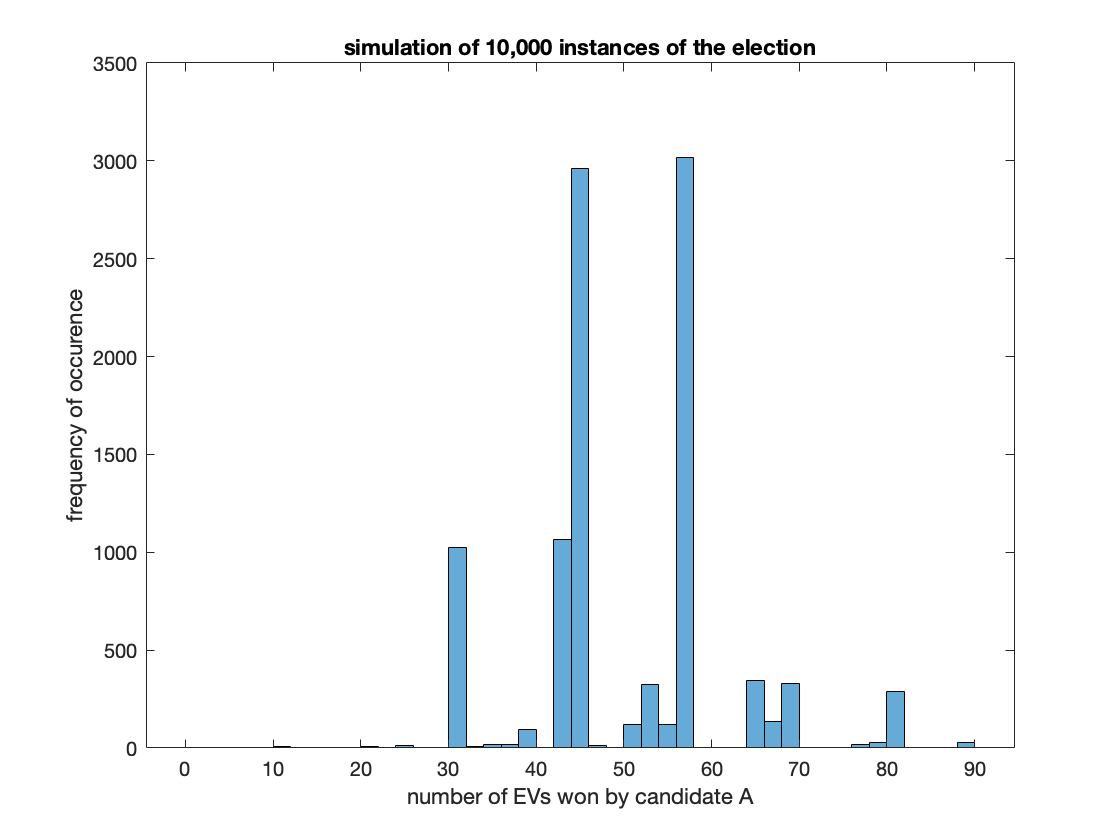

%put your work below
EVs_won_by_A = zeros(1,N);
for i = 1:N
    EVs_won_this_election = 0;
    for state_num = 1:num_states
        if probs(state_num)>rand([1,1])
            EVs_won_this_election = EVs_won_this_election + EVs(state_num);
        end
    end
    EVs_won_by_A(i) = EVs_won_this_election;
end
histogram(EVs_won_by_A)
xlabel("number of EVs won by candidate A")
ylabel("frequency of occurence")
title("simulation of 10,000 instances of the election")

b) (5 points) What is the probability of an electoral college tie (each candidate gets 269 EVs)? What is the probability that candidate A wins?

% Put your work below
tieval = 269-230;
winmin = tieval+1;
num_won = 0;
num_tied = 0;
for EVval = EVs_won_by_A
    if EVval==tieval
        num_tied = num_tied + 1;
    elseif EVval>winmin
        num_won = num_won+1;
    end
end
prob_tie = num_tied/N

prob_tie = 0.0094

prob_Awin = num_won/N

prob_Awin = 0.8796

c) (5 points) What is the mean and standard deviation on the predicted number of EVs won by candidate A?

%Put your work below
mean(EVs_won_by_A)

ans = 49.5192

var(EVs_won_by_A)

ans = 135.3128

function prob_d_e = P_de(a,d,e)
    p_x = @(x) (a.^2)-(x.^2);
    num = integral(p_x,d,e);
    den = integral(p_x,-a,a);
    prob_d_e = num/den;
end